k_e_init = 9.5; k_b_init = 10 - k_e_init; k_e = k_e_init; k_b = 0; % define initial rates
k = k_e + k_b; % k_tot
n_steps = 5000; N = 1; % define number of steps and serial number of branch
L_crit = 3; % minimum length needed for branching
position = 0; % where on filament branching occurs
r=12;

k_bj = kbfunc(0,k_b_init,L_crit); % will keep updating as a new filament is added
prob_b = zeros(1,N); % initialize array of branching weights for each filament
direction = 0; % left/right direction at which filament grows
x = 0; % starting x-coord 
y = 0; % starting y-coord
t1_x = r; t1_y = 0; % target 1
t2_x = r*cosd(45); t2_y = r*sind(45); % target 2
t3_x = 0; t3_y = r; % target 3
t4_x = -r*cosd(45); t4_y = r*sind(45); % target 4
t5_x = -r; t5_y = 0; % target 5
t6_x = -r*cosd(45); t6_y = -r*sind(45); % target 6
t7_x = 0; t7_y = -r; % target 7
t8_x = r*cosd(45); t8_y = -r*sind(45); % target 8
targets = [1 2 3 4 5 6 7 8 ; 1 1 1 1 1 1 1 1]; % 1 = not hit ; 2 = hit
t_reached = 0;

distance = NaN; % distance from end point of filament to target
d_opt = 2; % distance required for target to be reached / radius of target

system = [1 zeros(1, n_steps - 1)];  % initialize system variable; 1 = elongate, 2 = branch
info = [0 0 1 0 0 0 0 0]; % initialize data table
% x-coord ; y-coord ; N ; N of mother branch ; length of filament; angle;
% end-x ; end-y

t_int = zeros(1,n_steps); % initialize time intervals
t_int(1) = exprnd(1/k); % randomized time interval

pick = 0; pick_e = 0; % pick_b = ? % initialize pick variable
for i = 2:n_steps
    c = rand(); % to pick elongate/branch
    t = exprnd(1/k); % time interval
    for j = 1:length(k_bj) 
        k_bj(j) = kbfunc(info(j,5), k_b_init, L_crit); % update branching rates
    end
    k_b = sum(k_bj);
    if c < k_e/(k_e+k_b) %|| sum(info(:,5) >= L_crit) < 1 % elongate (also elongating if no filament can branch yet)
        pick = 1; % system is elongating
        pick_e = fix(rand()*N) + 1; % pick which filament to elongate
        info(pick_e, 5) = info(pick_e, 5) + 1; % update data table
        end_x = info(pick_e,1) + info(pick_e,5)*cosd(info(pick_e,6));
        end_y = info(pick_e,2) + info(pick_e,5)*sind(info(pick_e,6)); % end pt coordinates of filament
        if sqrt((end_x - t1_x)^2 + (end_y - t1_y)^2) < d_opt % filament has hit the target
            if targets(2,1) == 1
                targets(2,1) = 2;
                t_reached = t_reached + 1
            end
        elseif sqrt((end_x - t2_x)^2 + (end_y - t2_y)^2) < d_opt
            if targets(2,2) == 1
                targets(2,2) = 2;
                t_reached = t_reached + 1
            end
        elseif sqrt((end_x - t3_x)^2 + (end_y - t3_y)^2) < d_opt
            if targets(2,3) == 1
                targets(2,3) = 2;
                t_reached = t_reached + 1
            end
        elseif sqrt((end_x - t4_x)^2 + (end_y - t4_y)^2) < d_opt
            if targets(2,4) == 1
                targets(2,4) = 2;
                t_reached = t_reached + 1
            end
        elseif sqrt((end_x - t5_x)^2 + (end_y - t5_y)^2) < d_opt
            if targets(2,5) == 1
                targets(2,5) = 2;
                t_reached = t_reached + 1
            end
        elseif sqrt((end_x - t6_x)^2 + (end_y - t6_y)^2) < d_opt
            if targets(2,6) == 1
                targets(2,6) = 2;
                t_reached = t_reached + 1
            end
        elseif sqrt((end_x - t7_x)^2 + (end_y - t7_y)^2) < d_opt
            if targets(2,7) == 1
                targets(2,7) = 2;
                t_reached = t_reached + 1
            end
        elseif sqrt((end_x - t8_x)^2 + (end_y - t8_y)^2) < d_opt
            if targets(2,8) == 1
                targets(2,8) = 2;
                t_reached = t_reached + 1
            end
        end
        if t_reached == 8
            break
        end
    else
        pick = 2; % system is branching
        k_bj = [k_bj 0]; % rate for new branch
        info = [info; zeros(1, width(info))]; % new row in data table
        prob_b = k_bj./sum(k_bj); % array of branching weights for each filament
        mother_b = randsample(1:N+1,1,true,prob_b); % pick where to branch
        direction = pick_dir(); % randomly picks whether to branch left or right
        N = N + 1; % new filament
        k_b = sum(k_bj);
        k_e = N*k_e_init;
        k = k_e + k_b; % update rates
        info(N,3) = N; % update serial number of new filament
        info(N,4) = mother_b; % update location of new branch
        info(N,6) = calc_angle(direction,info(mother_b, 6)); % recording angle
        position = randi(info(mother_b,5),1); % where on mother branch to create new branch
        x = info(mother_b, 1) + position*cosd(info(mother_b,6));
        y = info(mother_b, 2) + position*sind(info(mother_b,6)); % calculating coordinates of start point
        info(N,1) = x;
        info(N,2) = y; % recording coordinates of start point
    end
    system(i) = pick; % update system
    t_int(i) = t; % update time intervals
end

t_reached = 1

t_reached = 2

t_reached = 3

t_reached = 4

t_reached = 5

t_reached = 6

% cumsum(t_int)
% system
% info % display results

x_end = info(:,1) + info(:,5).*cosd(info(:,6));
y_end = info(:,2) + info(:,5).*sind(info(:,6)); % end points of filaments
info(:,7) = x_end;
info(:,8) = y_end;
info

info =          0         0    1.0000         0   36.0000         0   36.0000         0
    3.0000         0    2.0000    1.0000   42.0000  290.0000   17.3648  -39.4671
    4.0000         0    3.0000    1.0000   35.0000  290.0000   15.9707  -32.8892
    7.0000         0    4.0000    1.0000   21.0000   70.0000   14.1824   19.7335
   10.0000         0    5.0000    1.0000   24.0000  290.0000   18.2085  -22.5526
   12.0000         0    6.0000    1.0000   29.0000  290.0000   21.9186  -27.2511
    7.1042  -11.2763    7.0000    2.0000   20.0000  220.0000   -8.2166  -24.1321
    8.1303  -14.0954    8.0000    2.0000   19.0000  220.0000   -6.4245  -26.3084
    7.4463  -12.2160    9.0000    2.0000   21.0000         0   28.4463  -12.2160
   11.0000         0   10.0000    1.0000   19.0000  290.0000   17.4984  -17.8542


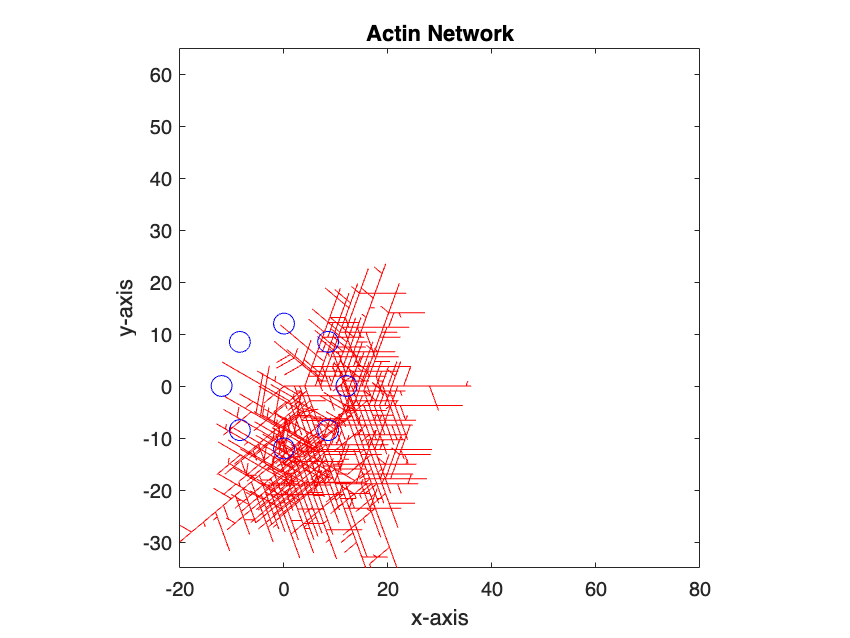


plot([info(:,1)';x_end'], [info(:,2)';y_end'],'r') % plotting actin network
title("Actin Network")
xlabel("x-axis")
ylabel("y-axis")
xlim([-20 80])
ylim([-35 65])
pbaspect([1 1 1])

hold on
theta = linspace(0,2*pi,200);
c1_x = t1_x + d_opt*cos(theta);
c1_y = t1_y + d_opt*sin(theta);
plot(c1_x,c1_y,'b')

c2_x = t2_x + d_opt*cos(theta);
c2_y = t2_y + d_opt*sin(theta);
plot(c2_x,c2_y,'b')

c3_x = t3_x + d_opt*cos(theta);
c3_y = t3_y + d_opt*sin(theta);
plot(c3_x,c3_y,'b')

c4_x = t4_x + d_opt*cos(theta);
c4_y = t4_y + d_opt*sin(theta);
plot(c4_x,c4_y,'b')

c5_x = t5_x + d_opt*cos(theta);
c5_y = t5_y + d_opt*sin(theta);
plot(c5_x,c5_y,'b')

c6_x = t6_x + d_opt*cos(theta);
c6_y = t6_y + d_opt*sin(theta);
plot(c6_x,c6_y,'b')

c7_x = t7_x + d_opt*cos(theta);
c7_y = t7_y + d_opt*sin(theta);
plot(c7_x,c7_y,'b')

c8_x = t8_x + d_opt*cos(theta);
c8_y = t8_y + d_opt*sin(theta);
plot(c8_x,c8_y,'b')
hold off